## Problem 2

### Part a

Reformulated State Space Model:

m1 = 1;
m2 = 1;
k = 1;

A = [0 0 1 0
        0 0 0 1
      -k/m1 k/m1 0 0
       k/m2 -k/m2 0 0];

B = [ 0    0
      0    0
    1/m1   0
      0  1/m2];


C = [ 0 1 0 0];

D = [0 0];

ss_sys = ss(A,B,C,D) %State Space system

ss_sys =
 
  A = 
       x1  x2  x3  x4
   x1   0   0   1   0
   x2   0   0   0   1
   x3  -1   1   0   0
   x4   1  -1   0   0
 
  B = 
       u1  u2
   x1   0   0
   x2   0   0
   x3   1   0
   x4   0   1
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



System Transfer Function:

[num, den] = ss2tf(A,B,C,D,1);

tf_sys = tf(num,den)

tf_sys =
 
                           1
  ----------------------------------------------------
  s^4 - 1.89e-17 s^3 + 2 s^2 - 1.408e-16 s - 3.263e-32
 
Continuous-time transfer function.



### Part b

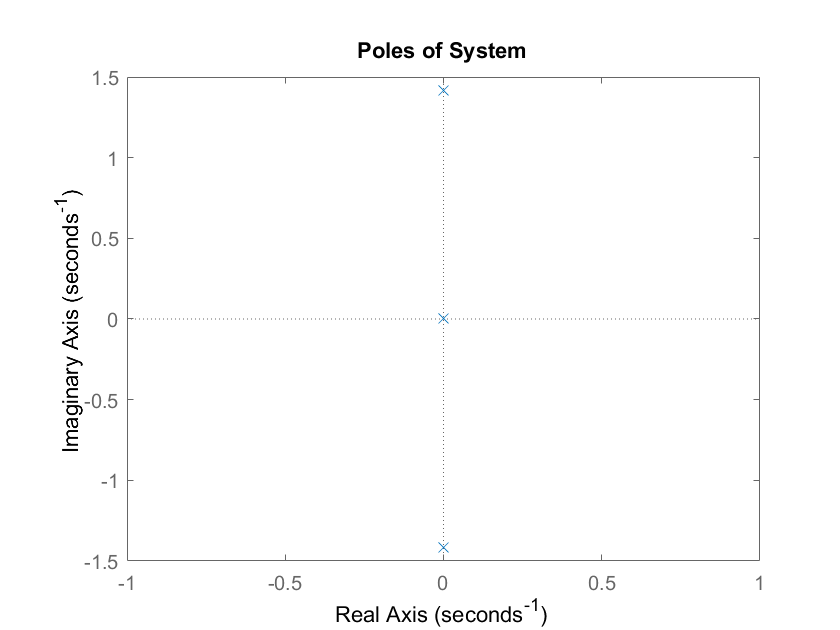

figure 
pzmap(tf_sys)
xlim([-1 1])
title('Poles of System')

### Part c

Choose transient properties:

POS = 10; %10 percent overshoot
ST = 1; %Settling time of 1 second
Tol_frac = 0.02; %Tolerance fraction of 2%
Ts = 1; %Settling time is 1 second

DR = -log(POS/100)/sqrt(pi^2 + log(POS/100)^2) %Damping Ratio as Function of percent overshoot

DR = 0.5912